Projection motion solver. -Charles Sun

based on the video by Professor Dave Explains

[https://www.youtube.com/watch?v=aY8z2qO44WA](https://www.youtube.com/watch?v=aY8z2qO44WA)

**Problem: If we throw a rock at 8.5 m/s  at 30 degrees angle on top of a 100 m cliff,  (1) How long is the rock in the air?  (2) How far away from the cliff will the rock land?**

The applicable kinematic equations:

eq1: d = d0 + vi*t + 1/2*a*t^2

given:

we starts at the origin of the coordinates, so d0=0 for both x and y axis.

vi =8.5  ;  % initial velocity
theta = 30; % launch angle in degrees
ax = 0 ;    % no acceleration on x direction
ay = -9.8;  % gravity, acceleration on y direction

Firist, we find x & y components of vi using cosine and sine functions. 

vx = vi * cosd(theta) % use cosd() for degree input 

vx = 7.3612

vy = vi * sind(theta) % use cosd() for degree input 

vy = 4.2500

Next, we work on y-axis &  apply eq1 to solve for the time t for the rock to land at y=-100.

-100 = 0 + vy * t + 0.5 * ay * t^2

Put it in a quadratic form:

0.5*ay*t^2 + vy*t +100 = 0

[t1, t2] = qsolver(0.5*ay, vy, 100)

t1 = -4.1046

t2 = 4.9720

 Here, we select the positive t result because t>0. That is our answer for Q1.

if t1 > 0
    t=t1
else 
    t=t2    
end

t = 4.9720

fprintf("ANSWER #1: The rock stays in air for %.2f seconds.", t)

ANSWER #1: The rock stays in air for 4.97 seconds.

Next, we apply eq1 on x-axis to find how far it will travel.   

dx = 0 + vx*t + 0.5*ax*t^2  

dx = 36.5998

fprintf("ANSWER #2: The rock travel %.2f meters from cliff.", dx)

ANSWER #2: The rock travel 36.60 meters from cliff.

**BONUS QUESTION: What is the maximum height the ball will reach?**

Note when the maximum height dy is reached, vy = 0. So we solve for dy when vy=0.  

The applicable kinematic equation is:

vf^2 = vi^2 + 2*a*d  

Apply it to y-axis when maximum height is reached...

vyf=0;  %  final velocity at max height
dy = (vyf^2 - vy^2) / (2*ay) 

dy = 0.9216

fprintf("BONUS ANSWER: The maximum height is %.2f meters.", dy)

BONUS ANSWER: The maximum height is 0.92 meters.

Let's plot the path...

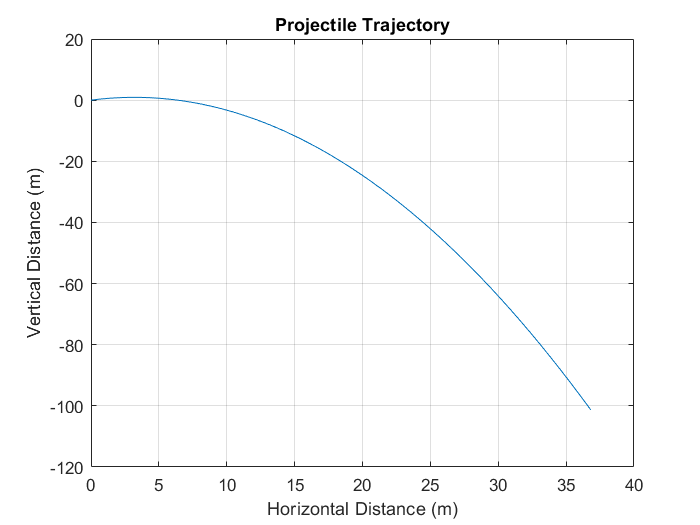

% create a time array 
t = 0:0.1:5;
% Calculate projectile x,y positions at each pt in time using eq1
x = vx * t;
y = vy * t + 0.5 * ay * t.^2;
% Plot the trajectory
plot(x, y); 
xlabel('Horizontal Distance (m)');
ylabel('Vertical Distance (m)');
title('Projectile Trajectory');
grid on;

function [x1,x2] = qsolver( a, b, c )
% quadratic equation solver
% a, b, c are coefficients: ax^2+bx+c=0
x1 = (-b+sqrt(b^2-4*a*c)) / (2*a);
x2 = (-b-sqrt(b^2-4*a*c)) / (2*a);
end